% Code must be run in order by section.

dat = readtable("bananas.csv");  % imports the table
dat.Origin = categorical(dat.Origin);
Country = categories(dat.Origin);
Country'  % formats the output

ans = 1×27 cell array
    {'acp_bananas'}    {'all_bananas'}    {'belize'}    {'brazil'}    {'cameroon'}    {'colombia'}    {'costa_rica'}    {'dollar_bananas'}    {'dominican_republic'}    {'ecuador'}    {'eu_bananas'}    {'ghana'}    {'guadeloupe'}    {'guatemala'}    {'honduras'}    {'ivory_coast'}    {'jamaica'}    {'malaysia'}    {'martinique'}    {'mexico'}    {'nicaragua'}    {'panama'}    {'somalia'}    {'st_vincent'}    {'surinam'}    {'venezuela'}    {'windward_isles'}


av = {};

for i = 1:27
    
    T = dat(dat.Origin == Country{i},:);  % isolates data from each country
    T = sortrows(T,2,'descend');  % sort by date, most recent at the top
    m_r = T{1,'Date'};  % datetime value of most recent date
    
    T = table2timetable(T);  % switch to timetable in order to select by timerange
    T = T(timerange(m_r-years(5),m_r,'closed'),:);  % isolates the last 5 years of data
    av{i} = mean(T{:,'Price'});  % updates list of averages with each country's average   
end

Average_Price = av';  % so dimensions match in table function below
Units = cell(27,1);
Units(:) = {'£/kg'};  % units column
A = table(Country,Average_Price,Units);  % tabulates the data for the averages
A = sortrows(A,2,'descend');  % sorts by average price, ascending

top_3 = A(1:3,:)

top_3 = 3×3 table
       Country        Average_Price     Units  
    ______________    _____________    ________

    {'somalia'   }     {[0.8300]}      {'£/kg'}
    {'panama'    }     {[0.7890]}      {'£/kg'}
    {'costa_rica'}     {[0.7690]}      {'£/kg'}


% a bit of formatting, the bottom 3 are shown in ascending order
bottom_3 = sortrows(A(25:27,:),2,'ascend')

bottom_3 = 3×3 table
         Country          Average_Price     Units  
    __________________    _____________    ________

    {'windward_isles'}     {[0.4703]}      {'£/kg'}
    {'surinam'       }     {[0.5071]}      {'£/kg'}
    {'venezuela'     }     {[0.5227]}      {'£/kg'}


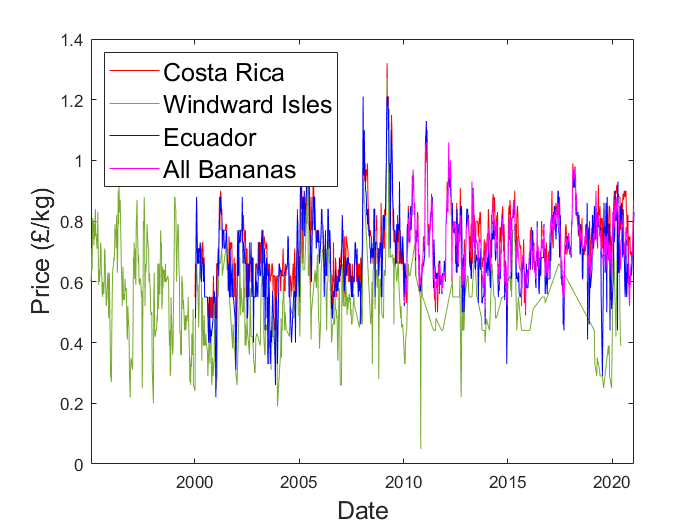

T1 = dat(dat.Origin == 'costa_rica',:);  % sub-tables with the data for each specified country
T2 = dat(dat.Origin == 'windward_isles',:);
T3 = dat(dat.Origin == 'ecuador',:);
T4 = dat(dat.Origin == 'all_bananas',:);

p = plot(T1.Date,T1.Price,'r',...
    T2.Date,T2.Price,...
    T3.Date,T3.Price,'b',...
    T4.Date,T4.Price,'m');

p(2).Color = [0.4660 0.6740 0.1880];  % special line color

lg = legend('Costa Rica','Windward Isles',...
    'Ecuador','All Bananas','Location','northwest');  % legend
lg.FontSize = 15;

xlabel('Date','FontSize',15);  % axis labels
ylabel('Price (£/kg)','FontSize',15);

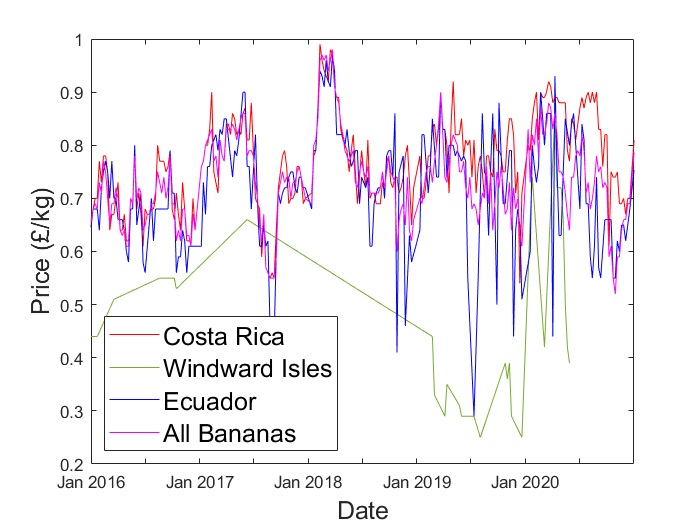

xlim([datetime(2016,1,1), datetime(2020,12,31)])  % same plot, x-axis limits shortened to the required timespan
lg.Location = 'southwest';  % formatting